**Will Tirone **

**MAT 275 **

**LAB 4**

**Question 1**

**a) **

type LAB04ex1.m

t0 = 0;
tf = 40; 
y0 = [-.5;.5];
[t,Y] = ode45(@f,[t0,tf],y0);
y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2

figure(1);
plot(t,y,'b',t,v,'r','Linewidth',2); 
ylabel('y, v = y''')
xlabel('t');
legend('y(t)','v(t)') 
ylim([-1.9,1.9]);
xlim([0,40]); 
grid on;

figure(2)
plot(y,v,'Linewidth',2); axis square; xlabel('y'); ylabel('v=y''');  % plot the phase plot
ylim([-1.9,1.9]);
xlim([-1.9,1.9]);  
grid on;
 %----------------------------------------------------------------------
 
function dYdt= f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; -5*sin(t)-7*v-6*y];
end


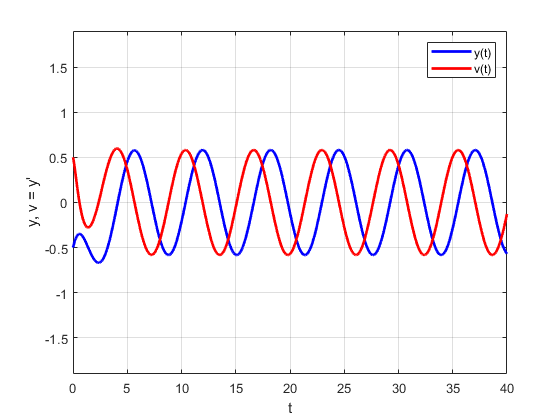

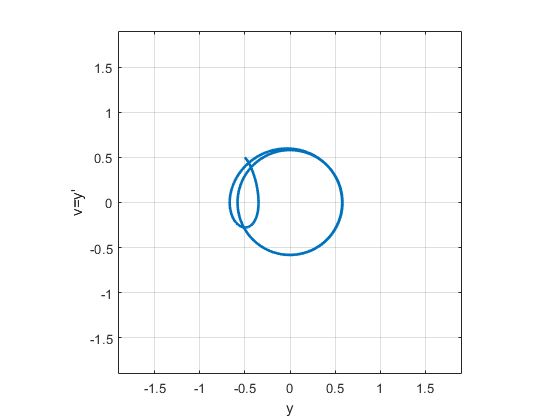

LAB04ex1

**b) **

y will reach a maximum when the derivative, v(t), is zero. I found these points by manually looking through the v(t) values and displaying the rows where the sign change occurs. I also compared this to the plot at the various t values to confirm that y(t) had actually reached a maximum. 

A = [t,Y(:,1),Y(:,2)];
Maximum_Values = [A((430:431),:); A((538:539),:); A((646:647),:)];
T = table(Maximum_Values(:,1), Maximum_Values(:,2), Maximum_Values(:,3));
T.Properties.VariableNames = {'t','y(t)', 'v(t)'}; 
T

T = 6×3 table
      t        y(t)        v(t)   
    ______    _______    _________

    24.492    0.58112     0.011754
    24.539    0.58103    -0.015413
    30.775    0.58112     0.011744
    30.822    0.58103    -0.015423
    37.059    0.58112     0.011742
    37.105    0.58103    -0.015425


**c)**

It seems that the long term behavior of y is that it will continue to oscillate between -.5811 and .5811 as t approaches infinity. I believe this means it is an example of an undamped oscillation. I believe the long-term component of this could also be called the steady state solution. 

**d) **

I've modified the initial conditions to y(0) = -1 and v(0) = -1.6; this has not changed the long-term solution. This is because the transient, or complementary, solution is dependent on the initial conditions, while the steady state solution does not. This is supported graphically. 

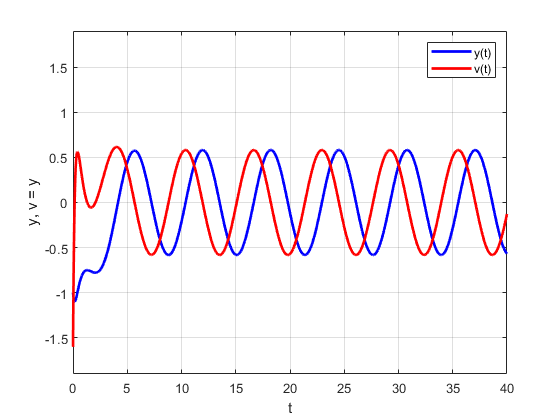

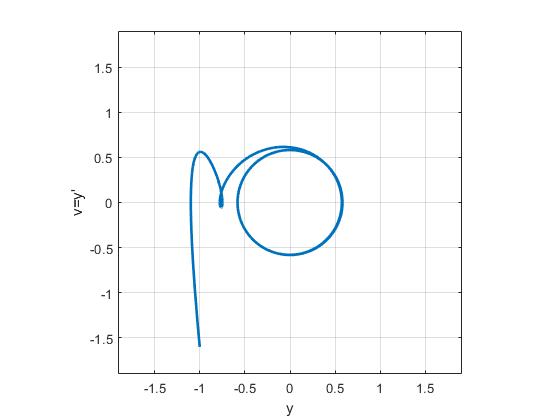

LAB04ex1

**Question 2**

**a) **

The only lines that were changed were the following in LAB04ex2 to redefine the ODE: 

**dYdt = [v; -5*sin(t)-7*v*(y^2)-6*y];**

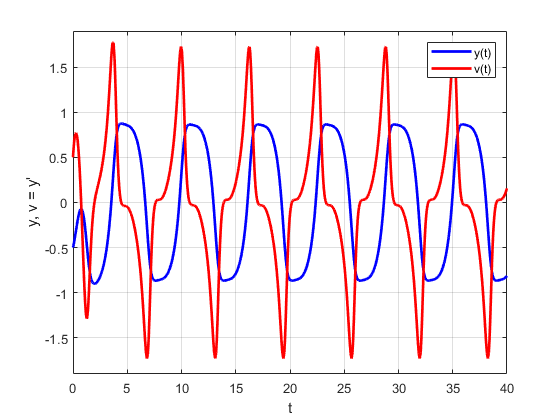

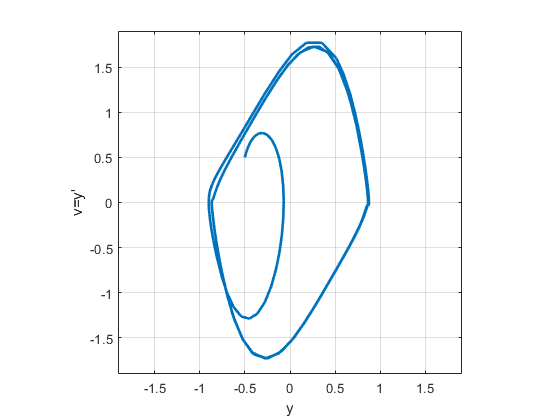

LAB04ex2

**b) Compare the output of Figs 7 and 8. Describe the changes in the behavior of the solution in the short term.**

the solution quickly reaches an "equilibrium" solution and moves into the steady-state solution at around t=2. It seems that this happened similar to the first example, while it happened faster than the second example with larger initial conditions. This means the "farther" away the initial conditions are, the longer the function with take to reach its long-term oscillation pattern. 

**c) Compare the long term behavior of both problems (4) and (7), in particular the amplitude of oscillations.**

While both (4) and (7) reach a long-term steady-state solution, the amplitude of (7) is larger. This is due to the $y^2
$ term in (7). Additionally, $\frac{dy}{dx}$ for (7) has a much larger amplitude than that of (4). 

**d) **

The solutions below (Euler's approximation in red and ODE45's solution in black) are very close but are not exactly the same. If N increases, v(t) will be a closer approximation to the actual solution. As discussed in Lab 3, since the standard Euler's method is a first-order solution, it will decrease the error by a factor of 10 each time. 

type LAB04ex2.m

t0 = 0;
tf = 40; 
y0 = [-.5;.5];
[t,Y] = ode45(@f,[t0,tf],y0,[]);

[te,Ye] = euler(@f, [0,40], y0, 600); 
y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2

figure(1);
plot(t,y,'k',te,Ye(:,1),'r--','Linewidth',2); 
ylabel('y, v = y''')
xlabel('t');
legend('y(t)','v(t)') 
ylim([-1.9,1.9]);
xlim([0,40]); 
grid on;

% figure(2)
% plot(y,v,'Linewidth',2); axis square; xlabel('y'); ylabel('v=y''');  % plot the phase plot
% ylim([-1.9,1.9]);
% xlim([-1.9,1.9]);  
% grid on;
 %----------------------------------------------------------------------
 
function dYdt= f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; -5*sin(t)-7*v*(y^2)-6*y];
end


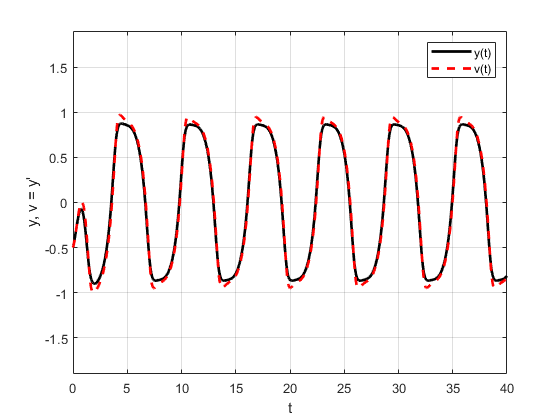

LAB04ex2

**Question 3) **

Solve numerically the IVP: 

$\frac{d^2y}{dt^2} + 7y\frac{dy}{dt} + 6y = -5sin(t) $  with $y(0) = -.5, \frac{dy}{dt}(0) = 0.5$ from $0 \leq t \leq 40$

**Comments: **the solutions below are very different from (7); it appears the solution goes to $-\infty$ as t increases. In addition, the error message below indicates that the step size cannot be made smaller to find a more precise solution; while I'm not sure how ode45 works exactly, I assume it is similar to Euler's method in that an N value is chosen which results in a given step size. A step size below 3.55e-15 is not allowed per the error. I've done some research online and it appears that because this function includes a singularity it cannot be integrated over that region. It's possible that changing the region of integration may solve this (if this were something that actually needed to be solved and not just for a lab); I would be curious to hear the actual solution / work around for an issue like this when solving real-world problems. 

type LAB04ex3.m

t0 = 0;
tf = 40; 
y0 = [-.5;.5];
[t,Y] = ode45(@f,[t0,tf],y0);
y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2

figure(1);
plot(t,y,'b',t,v,'r','Linewidth',2); 
ylabel('y, v = y''')
xlabel('t');
legend('y(t)','v(t)') 
ylim([-1.9,1.9]);
xlim([0,40]); 
grid on;

figure(2)
plot(y,v,'Linewidth',2); axis square; xlabel('y'); ylabel('v=y''');  % plot the phase plot
ylim([-1.9,1.9]);
xlim([-1.9,1.9]);  
grid on;
 %----------------------------------------------------------------------
 
function dYdt= f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; -5*sin(t)-7*y*v-6*y];
end


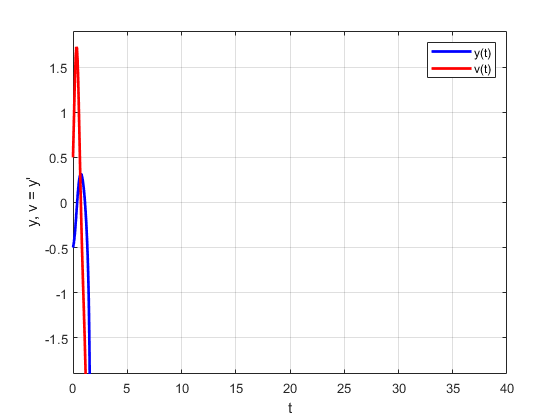

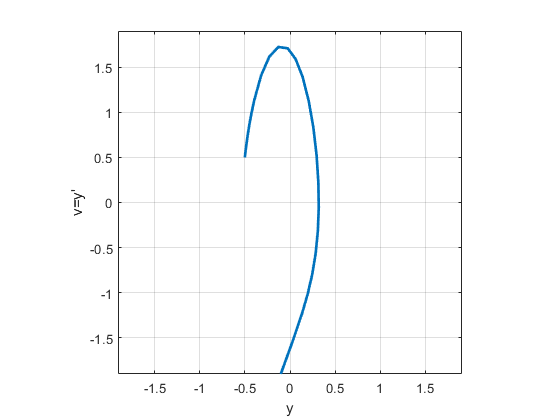

LAB04ex3

**Question 4**

type LAB04ex4.m

t0 = 0;
tf = 40; 
y0_v0_w0 = [-.5;.5;0];
[t,Y] = ode45(@f,[t0,tf],y0_v0_w0);
y=Y(:,1); v=Y(:,2); w=Y(:,3);    % y in output has 2 columns corresponding to u1 and u2

figure(1);
plot(t,y,'b',t,v,'r',t,w,'k','Linewidth',2); 
ylabel('y, v = y''')
xlabel('t');
legend('y(t)','v(t)','w(t)') 
ylim([-1.9,1.9]);
xlim([0,40]); 
grid on;

figure(2)
plot3(y,v,w,'Linewidth',2); 
axis square; 
view([-40,60])
xlabel('y'); 
ylabel('v=y'''); 
zlabel('w=y''''');
ylim([-1.9,1.9]);
xlim([-1.9,1.9]);  
grid on;
 %----------------------------------------------------------------------
 
function dYdt= f(t,Y)
y=Y(1); v=Y(2); w=Y(3); 
dYdt = [v; w; -5*cos(t)-7*(y^2)*w-14*y*v^2-6*v];
end


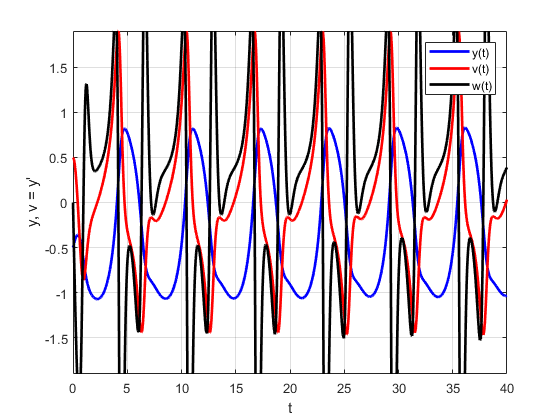

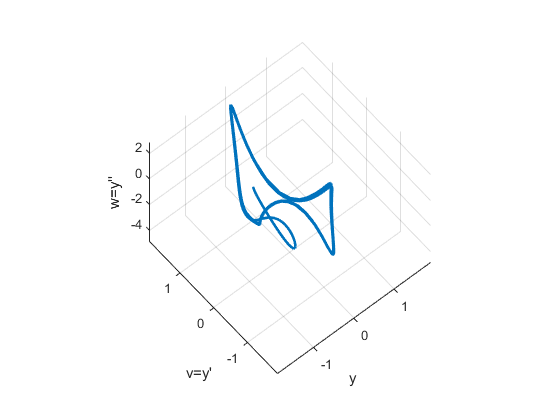

LAB04ex4